clear;
I = imread('test9.jpg');
check(I)

ans = 10×1 char array
    'I'
    'm'
    ' '
    'J'
    'o'
    's'
    'e'
    'p'
    'h'
    '!'


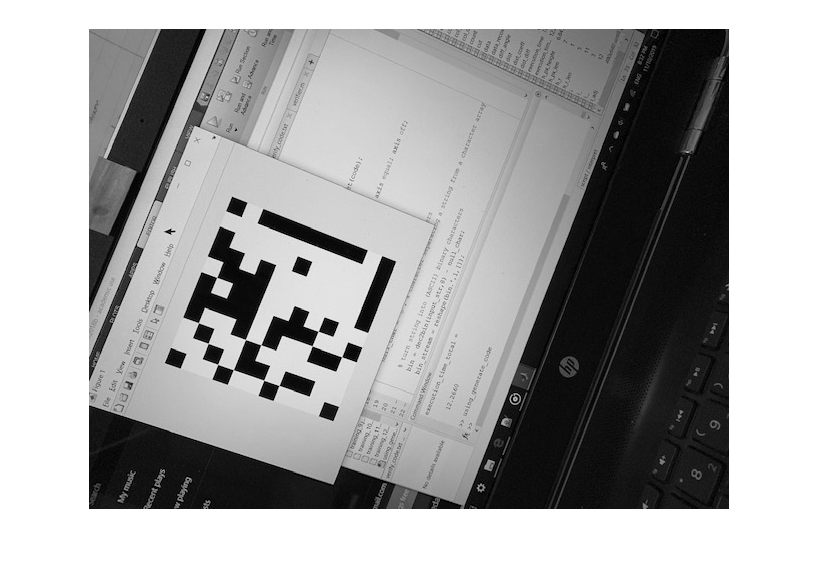



I = rgb2gray(I); % change to black and white image

if size(I, 1) > 2500 && size(I, 2) > 2500
    I = I(1:5:end, 1:5:end); % reduce the power of the iphone
end

input_image = I; % store original for later use
imshow(input_image) 

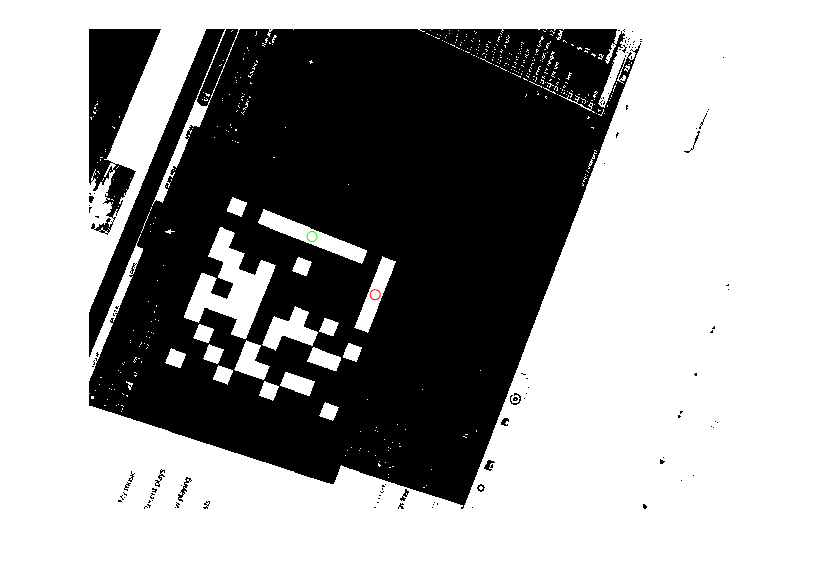


I = imadjust(I); % Contrast boost to make blacks more distinct
I = imbinarize(I,'global'); % threshold image using golbal method
I = imcomplement(I); % invert binarized image so region props can work properly

% retuns the location of possible guid bars with details
details = regionprops('table', I, 'MajorAxisLength','MinoraxisLength', 'Orientation', 'Centroid');

% store location of potential
P_loc_V = [];% vertical bars of size 7
P_loc_H = [];% horizontal bars of size 5



% find possible vertical bars from regionprops
for row = 1:size(details,1)
    ratio = details.MajorAxisLength(row)/details.MinorAxisLength(row); 
    % ratio can be really strict as a result of the quality from IphoneTM 
    % vertical bar must be longer than 50 pixels
    if ratio > 6.5 && ratio < 7.5 && details.MajorAxisLength(row) > 50
        P_loc_V = [P_loc_V row];
    end    
end
% use refference vertical bar to find possible horrizontal guid bars
unit_size = details.MajorAxisLength(P_loc_V(1,1)) / 7;
for row = 1:size(details,1)
    ratio = details.MajorAxisLength(row)/unit_size;     
    if ratio > 4 && ratio < 6
        P_loc_H = [P_loc_H row];
    end  
end



% Check if guide bars are orthogonal to each other 
% number of vertical guide bars indicates number of qr codes
for V = 1:size(P_loc_V, 2)
    for H = 1:size(P_loc_H, 2)
        angle(V, H) = abs(details.Orientation(P_loc_H(1,H)) - details.Orientation(P_loc_V(1, V)));
    end 
end

% find the pair of side bars by checking for orthorganlity
for V = 1:size(P_loc_V, 2)
    n=90;
    [val(V),idx(V)]=min(abs(angle(V,:)-n));
end
temp = [];
for H = 1:size(idx, 2)
    temp = [temp P_loc_H(1, idx(1,H))];
end
P_loc_H = temp;






imshow(I)

hold on
for col = 1:size(P_loc_V, 2)
    ellipse(5,5, details.Orientation(P_loc_V(1,col)) * -(pi()/180), details.Centroid(P_loc_V(1,col), 1), details.Centroid(P_loc_V(1,col), 2), 'g')
end

for col = 1:size(P_loc_H, 2)
    ellipse(5,5, details.Orientation(P_loc_H(1,col)) * -(pi()/180), details.Centroid(P_loc_H(1,col), 1), details.Centroid(P_loc_H(1,col), 2), 'r')
    
end
hold off

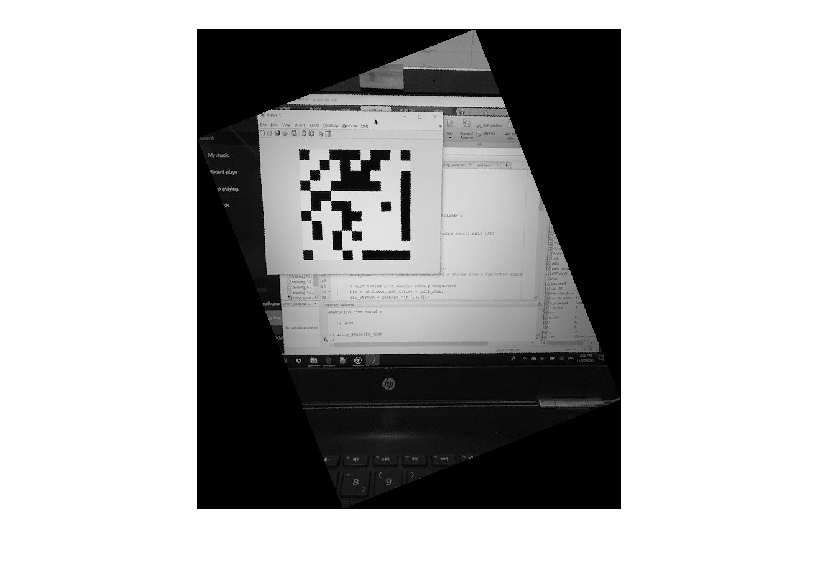


 col = 1;
%for col = 1:size(P_loc_V, 2)
    % rotate image to fix rotation of qr code
    alpha = -1 * details.Orientation(P_loc_H(1,col));    
%     if details.Centroid(P_loc_H(1,col), 2) < details.Centroid(P_loc_V(1,col), 2) || ...
%        details.Centroid(P_loc_V(1,col), 1) < details.Centroid(P_loc_H(1,col), 1)
%         alpha = alpha + 180;    
%     end
    rotatedIm = imrotate(input_image, alpha ); 
    imshow(rotatedIm)

    
     % find location of rotated points 
     V_y = round(details.Centroid(P_loc_V(1,col), 2));
     V_x = round(details.Centroid(P_loc_V(1,col), 1));
    canvas = zeros(size(input_image,1),size(input_image,2));
    canvas(V_y-1:V_y+1, V_x-1:V_x+1) = 1;
    canvas_rot = imrotate(canvas,alpha);
    [V_row, V_col] = find(canvas_rot);
    V_row = median(V_row);
    V_col = median(V_col);
    
    H_y = round(details.Centroid(P_loc_H(1,col), 2));
    H_x = round(details.Centroid(P_loc_H(1,col), 1));
    canvas = zeros(size(input_image,1),size(input_image,2));
    canvas(H_y-1:H_y+1, H_x-1:H_x+1) = 1;
    canvas_rot = imrotate(canvas,alpha);
    [H_row, H_col] = find(canvas_rot);
    H_row = median(H_row);
    H_col = median(H_col);
    
    % Fixes upside down QR code
    if H_row < V_row
        alpha = alpha + 180;
    end
    rotatedIm = imrotate(input_image, alpha ); 
    imshow(rotatedIm)

    

    
    
    
     % find location of rotated points 
     V_y = round(details.Centroid(P_loc_V(1,col), 2));
     V_x = round(details.Centroid(P_loc_V(1,col), 1));
    canvas = zeros(size(input_image,1),size(input_image,2));
    canvas(V_y-1:V_y+1, V_x-1:V_x+1) = 1;
    canvas_rot = imrotate(canvas,alpha);
    [V_row, V_col] = find(canvas_rot);
    V_row = median(V_row);
    V_col = median(V_col);
    
    H_y = round(details.Centroid(P_loc_H(1,col), 2));
    H_x = round(details.Centroid(P_loc_H(1,col), 1));
    canvas = zeros(size(input_image,1),size(input_image,2));
    canvas(H_y-1:H_y+1, H_x-1:H_x+1) = 1;
    canvas_rot = imrotate(canvas,alpha);
    [H_row, H_col] = find(canvas_rot);
    H_row = median(H_row);
    H_col = median(H_col);

    
    % find location of qr code bounds
    unit_size = details.MajorAxisLength(P_loc_V(1, col)) / 7;
    start_col = round(V_col - (unit_size * 10)); 
    end_col = round(V_col   + unit_size); 
    start_row = round(H_row - (unit_size * 10));
    end_row = round(H_row + unit_size);    
    
    if start_col < 1 
        start_col = 1;
    end
    if start_row < 1
        start_row = 1;
    end
    if end_col > size(rotatedIm, 2)
        end_col = size(rotatedIm, 2);
    end
    if end_row > size(rotatedIm, 1)
        end_row = size(rotatedIm, 1);
    end


   
    % extract block containing qr code
    window = rotatedIm([start_row:end_row],[start_col:end_col]);
    


    %imshow(window)
  
    
   
    
    qr = QReader(window);
    code2str(qr)

ans = 10×1 char array
    'I'
    'm'
    ' '
    'J'
    'o'
    's'
    'e'
    'p'
    'h'
    '!'


    
%end


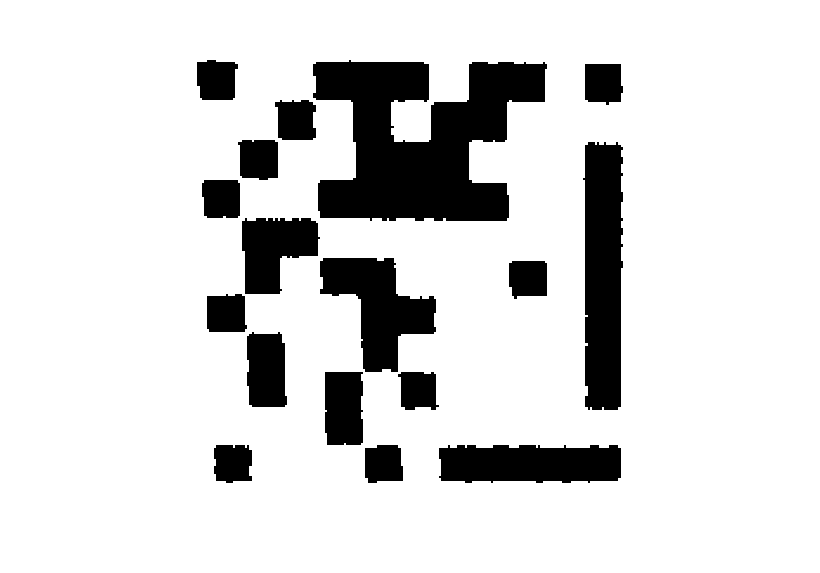


A = window;
A = medfilt2(A, 'symmetric');
A = imsharpen(A);
A = imbinarize(A,'global');
A = A * 255;

% Remove surrounding white space
A(1, :) = [];
A(:, 1) = [];
[m, n] = size(A);
count = 0;
imshow(A)

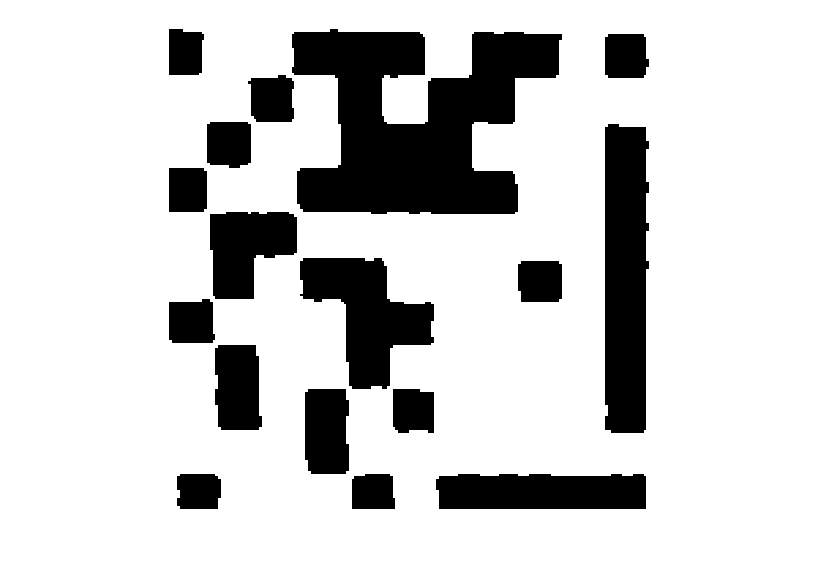

for row = 1:m
    for col = 1:floor(n/7)
        if A(row, col) < 112
            if count == 0
                start_col = col;
                start_row = row;
                count = 1;
            end
        end
    end
end


A2 = A([start_row:end], [ start_col:end]);
A2 = medfilt2(A2, 'symmetric');


[m, n] = size(A2);

count = 0;
for row = n:-1:1
    for col = m:-1:1
        if count == 0
            if A2(col, row) < 112
                count = 1;
                location1 = col;
                location2 = row;
            end         
        end
    end
end
if location2 > size(A2, 1)
    location2 = size(A2,1);
end
A2 = A2([1:location2], [1:location2]);
imshow(A2)

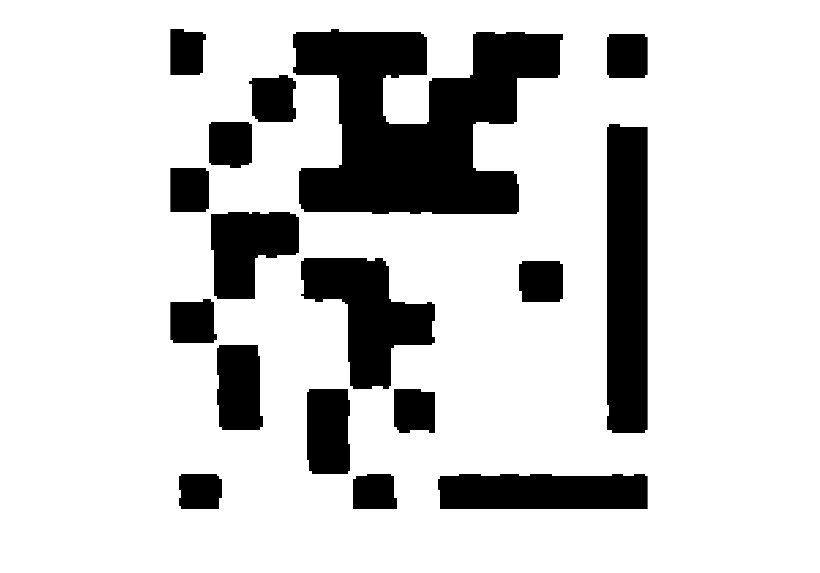

for index = 1:10
    [m, n] = size(A2);
        if A2(m, 6) == 255
            A2(m, :) = [];
        end
end

for index = 1:10
    [m, n] = size(A2);
        if A2(6, n) == 255
            A2(:, n) = [];
        end
end


imshow(A2)


% Turn into nested matrix
a  = size(A2, 1);
b  = size(A2, 2);
% number of elements in the matrix
numParts = 11;
c = floor(a/numParts);
d = rem(a, numParts);
partition_a = ones(1, numParts)*c;
partition_a(1:d) = partition_a(1:d)+1;
e = floor(b/numParts);
f = rem(b, numParts);
partition_b = ones(1, numParts)*e;
partition_b(1:f) = partition_b(1:f)+1;

output = mat2cell(A2, partition_a, partition_b);

%if avg is bellow 100 it means it was a black square which is 1
for row = 1:11
    for col = 1:11
        if mean(mean(output{row,col})) < 100
           qr(row,col) = 1;
        else 
           qr(row, col) = 0;
        end
    end
end
I = qr;
parsed = qr(:)';
%use side bars to determine if its a qr code or not
if qr(1,1) == 1 && qr(1,11) == 1 && qr(11,1) == 1 && qr(11, 11) == 1
    parsed([1, 2, 10, 11, 12, 13, 21, 22, 65, 66, 76, 77, 87, 88, 98, 99, ...
         100:end]) = [];
    %remove zero stuffing
    parsed([81, 82, 83]) = [];
    str = char(bin2dec(reshape(char(parsed+'0'), 8,[]).'))
else
    str = 'One non-QR code found!'
end

str = 10×1 char array
    'I'
    'm'
    ' '
    'J'
    'o'
    's'
    'e'
    'p'
    'h'
    '!'
